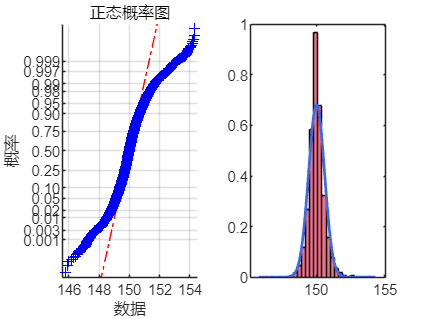

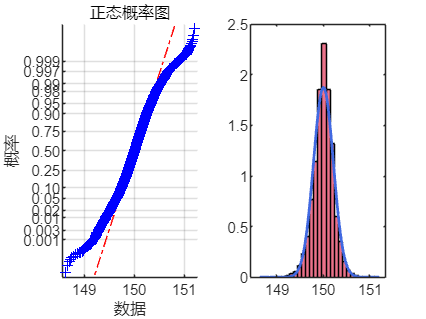

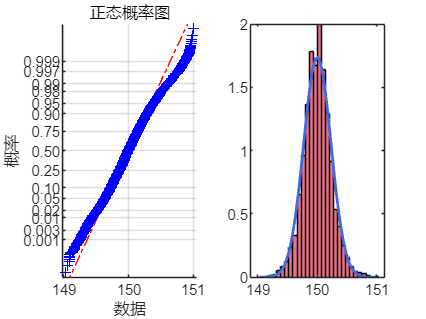

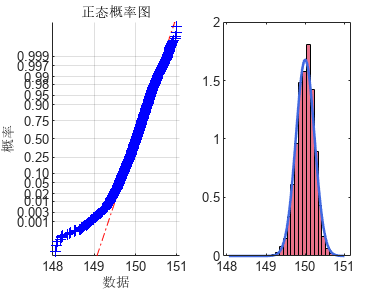

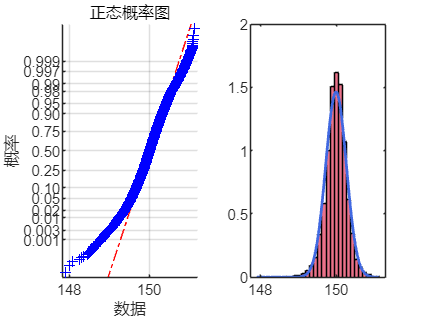

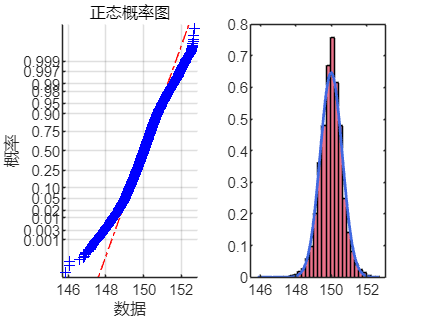

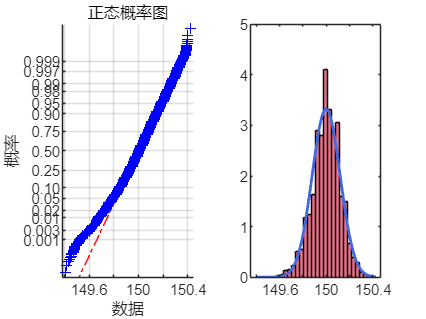

% Load data
run("ProgramFile\TemperatureAnalysis\LoadData_MethodTwo.m");
% Load color set
run("ProgramFile\ColorSet\Color.m");

% Define the enum type to choose the way to draw line charts.
way_to_draw = enum_way_to_draw.DRAW_OFF ;

% Define the enum type to decide whether to fit the normal distribution.
way_to_fit = enum_fit_norm_status.FIT_NORM_ON ;


% ------------------------------ Draw the line charts ------------------------------

% ========== Draw a basic line charts ==========
if way_to_draw == enum_way_to_draw.DRAW_BY_DATE
    close all;
    clc;
    for i = 1:1:7
        figure;
        for j = 1:1:FILES_NUM
            % According to the number of files determine the layout.
            if (FILES_NUM <4)
                subplot(1, FILES_NUM, j);
            else
                subplot(2, floor(FILES_NUM/2)+1, j);
            end
            plot(xaxiscell{j}, table2array(datacell{1, j}(:, i)), ...
                "DisplayName", sprintf("FileID: %s",namestr{j}), ...
                "LineWidth", 1.5);
            hold on;
            plot(xaxiscell{j}, repmat(statisticaldata{j}(1, i), height(datacell{1, j}), 1), ...
                "DisplayName", sprintf("AVG: %.6f", statisticaldata{j}(1, i)), ...
                "LineWidth", 1.1, ...
                "LineStyle", ":");
            set(gca,'Box','off', ...                                
                'LineWidth',1, ...                                  
                'XGrid','off','YGrid','on', ...                     
                'TickDir','out','TickLength',[0.01 0.01], ...       
                'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
            legend;
            colororder(color1006);
            hold off;
        end
    end
end

% ========== Just draw line charts with single file ==========
if way_to_draw == enum_way_to_draw.DRAW_WITH_ONE_FILE
    close all;
    clc;
    for j = 1:1:FILES_NUM
        if namestr{j} == "202408301709"
            for i = 1:1:7
                figure;
                plot(xaxiscell{j}, table2array(datacell{1, j}(:, i)), ...
                    "DisplayName", sprintf("FileID: %s",namestr{j}), ...
                    "LineWidth", 1.5);
                hold on;
                plot(xaxiscell{j}, repmat(statisticaldata{j}(1, i), height(datacell{1, j}), 1), ...
                    "DisplayName", sprintf("AVG: %.6f", statisticaldata{j}(1, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", ":");
                hold on;
                plot(xaxiscell{j}, repmat(statisticaldata{j}(1, i) - 3 * statisticaldata{j}(2, i), height(datacell{1, j}), 1), ...
                    "DisplayName", sprintf("-3σ: %.6f", statisticaldata{j}(1, i) - 3 * statisticaldata{j}(2, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", "--");
                hold on;
                plot(xaxiscell{j}, repmat(statisticaldata{j}(1, i) + 3 * statisticaldata{j}(2, i), height(datacell{1, j}), 1), ...
                    "DisplayName", sprintf("+3σ: %.6f", statisticaldata{j}(1, i) + 3 * statisticaldata{j}(2, i)), ...
                    "LineWidth", 1.1, ...
                    "LineStyle", "--");
                title(sprintf("Temperature line chart on position %d of file %s", i, namestr{j}),'FontSize',16);
                set(gca,'Box','off', ...                                
                    'LineWidth',1, ...                                  
                    'XGrid','off','YGrid','on', ...                     
                    'TickDir','out','TickLength',[0.01 0.01], ...       
                    'XMinorTick', 'off', 'YMinorTick', 'off', ...       
                    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       
                legend;
                colororder(color1006);
                hold off;
            end
        end
    end
end




% ------------------------------ Fit the normal distribution ------------------------------
if way_to_fit == enum_fit_norm_status.FIT_NORM_ON
    close all;
    clc;
    for j = 1:1:FILES_NUM
        if namestr{j} == "202408301709"
            for i = 1:1:7
                figure;
                normdata = table2array(ssdatacell{1, j}(:, i));
                subplot(1, 2, 1);
                normplot(normdata);
                [normdata_mu, normdata_sigma] = normfit(normdata);
                norm_x = linspace(min(normdata), max(normdata), 100);
                norm_fitted = normpdf(norm_x, normdata_mu, normdata_sigma);
                subplot(1, 2, 2);
                histogram(normdata, 30, 'Normalization', 'pdf');
                hold on;
                plot(norm_x, norm_fitted, 'LineWidth', 1.5);
                colororder(color1006);
                hold off;
            end
        end
    end
end